clear; clc; close all;

## Define Quadcopter Parameters

A_thrust = 0.091492681;
B_thrust = 0.067673604;
L = 0.046;
C_tau = 0.005964552;
d = L * (sqrt(2)/2);

% Physical Force Limits per motor (Based on ratio 0.0 to 1.0)
F_min = 0;
F_max = A_thrust*(1)^2 + B_thrust*(1); 

## Task 5: Visualize Thrust and Moments vs PWM Percentage

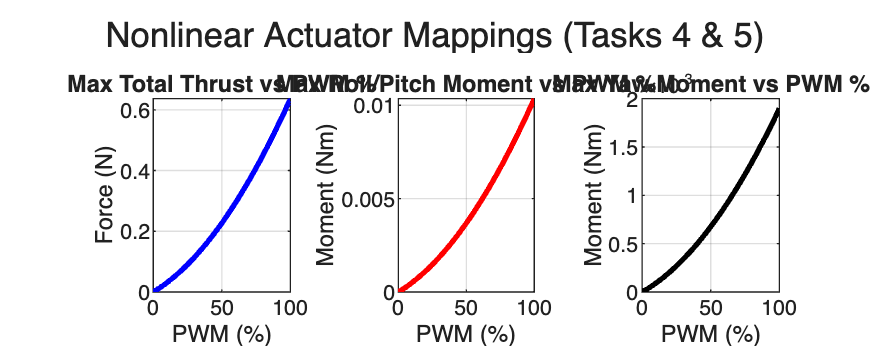

pwm_pct_plot = linspace(0, 100, 100);
pwm_ratio_plot = pwm_pct_plot / 100;

% Nonlinear forces
F_plot = A_thrust * (pwm_ratio_plot.^2) + B_thrust * pwm_ratio_plot;

figure('Position', [100, 100, 1000, 400]);

% Plot Total Thrust
subplot(1,3,1);
plot(pwm_pct_plot, 4 * F_plot, 'b', 'LineWidth', 2);
title('Max Total Thrust vs PWM %');
xlabel('PWM (%)'); ylabel('Force (N)'); grid on;

% Plot Roll/Pitch Moment 
subplot(1,3,2);
plot(pwm_pct_plot, 2 * d * F_plot, 'r', 'LineWidth', 2);
title('Max Roll/Pitch Moment vs PWM %');
xlabel('PWM (%)'); ylabel('Moment (Nm)'); grid on;

% Plot Yaw Moment
subplot(1,3,3);
plot(pwm_pct_plot, 2 * C_tau * F_plot, 'k', 'LineWidth', 2);
title('Max Yaw Moment vs PWM %');
xlabel('PWM (%)'); ylabel('Moment (Nm)'); grid on;

sgtitle('Nonlinear Actuator Mappings (Tasks 4 & 5)');

## Test the Mixer (Tasks 1, 2, 3)

Let's command hover thrust + an aggressive roll command

Fc_cmd = 0.323; % ~Hover weight
Lc_cmd = 0.8; % Aggressive roll
Mc_cmd = 0.8;
Nc_cmd = 0;

[pwm_outputs, F_actual] = quad_mixer(Fc_cmd, Lc_cmd, Mc_cmd, Nc_cmd, A_thrust, B_thrust, d, C_tau, F_min, F_max);

disp('--- Commanded vs Actual ---');

--- Commanded vs Actual ---


fprintf('Commanded Forces: [%.4f, %.4f, %.4f, %.4f] N\n', Fc_cmd, Lc_cmd, Mc_cmd, Nc_cmd);

Commanded Forces: [0.3230, 0.8000, 0.8000, 0.0000] N


fprintf('Required Motor PWMs (%%): [%.1f%%, %.1f%%, %.1f%%, %.1f%%]\n', pwm_outputs(1), pwm_outputs(2), pwm_outputs(3), pwm_outputs(4));

Required Motor PWMs (%): [63.3%, 0.0%, 63.3%, 100.0%]


## The Mixer Function

function [pwm_pct, F_des] = quad_mixer(Fc, Lc, Mc, Nc, A, B, d, C_tau, F_min, F_max)
    
    % 1. Linear Mapping Matrix
    M_mix = [1,      1,      1,      1; 
            -d,     -d,      d,      d; 
             d,     -d,     -d,      d; 
             C_tau, -C_tau,  C_tau, -C_tau];
         
    % Calculate desired forces
    U_cmd = [Fc; Lc; Mc; Nc];
    F_des = M_mix \ U_cmd;
    
    % 2 & 3. Actuator Saturation & Infeasible Command Handling
    % Strategy: Shift forces to preserve moments, scale if impossible.
    
    if max(F_des) > F_max
        % Shift down (Sacrifice altitude to keep attitude)
        shift = max(F_des) - F_max;
        F_des = F_des - shift;
    end
    
    if min(F_des) < F_min
        % Shift up
        shift = F_min - min(F_des);
        F_des = F_des + shift;
    end
    
    % If the spread is wider than physical limits, we must scale moments down
    if (max(F_des) - min(F_des)) > (F_max - F_min)
        mid_req = mean(F_des);
        mid_phys = (F_max + F_min) / 2;
        scale = (F_max - F_min) / (max(F_des) - min(F_des));
        
        % Center and scale
        F_des = mid_phys + scale * (F_des - mid_req);
    end
    
    % Final safety clamp against floating point errors
    F_des = max(min(F_des, F_max), F_min);
    
    % 4. Nonlinear Inversion (Force to PWM Ratio)
    % Solve: A*x^2 + B*x - F_des = 0 for positive root
    pwm_ratio = (-B + sqrt(B^2 + 4*A.*F_des)) ./ (2*A);
    
    % 5. Convert to valid percentage output
    pwm_pct = pwm_ratio * 100;
end

## fitting data

data = [0.24 0.0 4.01 0 0;
        0.37 1.6 3.98 6.25 4485;
        0.56 4.8 3.95 12.5 7570;
        0.75 7.9 3.92 18.75 9374;
        0.94 10.9 3.88 25 10885;
        1.15 13.9 3.84 31.25 12277;
        1.37 17.3 3.80 37.5 13522;
        1.59 21.0 3.76 43.25 14691;
        1.83 24.4 3.71 50 15924;
        2.11 28.6 3.67 56.25 17174;
        2.39 32.8 3.65 62.5 18179;
        2.71 37.3 3.62 68.75 19397;
        3.06 41.7 3.56 75 20539;
        3.46 46.0 3.48 81.25 21692;
        3.88 51.9 3.40 87.5 22598;
        4.44 57.9 3.30 93.75 23882];

thrust_data = data(:,2);
pwm_data = data(:, 4);
speed_data = data(:, 5);



cf_2 = fit(pwm_data, speed_data, 'poly2') %% we should probably change to poly3, we are underfitting right now. 

cf_2 =      Linear model Poly2:
     cf_2(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =      -1.434  (-2.073, -0.7948)
       p2 =       358.1  (296, 420.2)
       p3 =        2073  (818.2, 3328)

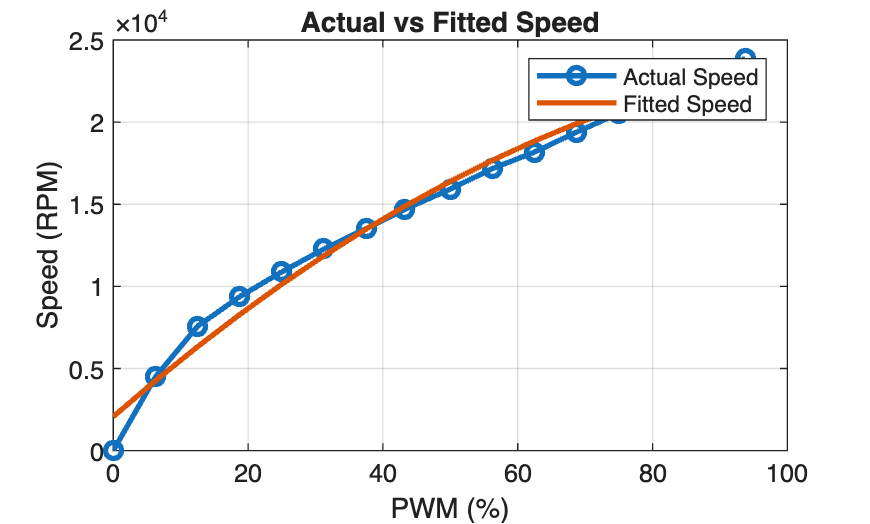


predicted_speed = cf_2(pwm_data);

% Plot the predicted speed against actual speed for comparison
figure;
plot(pwm_data, speed_data, '-o', 'DisplayName', 'Actual Speed', 'LineWidth',2);
hold on;
plot(pwm_data, predicted_speed, '-', 'DisplayName', 'Fitted Speed', 'LineWidth',2);
xlabel('PWM (%)');
ylabel('Speed (RPM)');
title('Actual vs Fitted Speed');
legend show;
grid on;
hold off;

## rebuild new model

% constant params
pwm_hover_value = 0.6408; %% value derived from previous assignment. 


A_thrust = 0.091492681;
B_thrust = 0.067673604;
L = 0.046;
drone_mass_kg = 0.033;

J = [16.571710 0.830806 0.718277;
      0.830806 16.655602 1.800197;
      0.718277 1.800197 29.261652].*10e-6;

Ts = 0.01; % SAMPLING TIME MUST CHANGE

num_d = 0.0304596;
den_d = [1 , -0.9695404];

sys_discrete = tf(num_d, den_d, Ts, 'Variable', 'z^-1');

sys_continuous = d2c(sys_discrete, 'zoh') % zero order hold 


sys_continuous =
 
  0.03046 s + 3.093
  -----------------
      s + 3.093
 
Continuous-time transfer function.



[A_act, B_act, C_act, D_act] = ssdata(sys_continuous); % continuous state space for the motor dynamics. 



%states (16now)
syms pn pe pd u v w phi theta psi p q r real

%motor state
syms pwm_act_1 pwm_act_2 pwm_act_3 pwm_act_4 real

% motor command input
syms pwm_cmd_1 pwm_cmd_2 pwm_cmd_3 pwm_cmd_4 real

state_vector_2 = [pn; pe; pd; u; v; w; phi; theta; psi; p; q; r; pwm_act_1; pwm_act_2; pwm_act_3; pwm_act_4];
input_vector_2 = [pwm_cmd_1; pwm_cmd_2; pwm_cmd_3; pwm_cmd_4];




% forces
F1 = A_thrust * pwm_act_1^2 + B_thrust*pwm_act_1;
F2 = A_thrust * pwm_act_2^2 + B_thrust*pwm_act_2;
F3 = A_thrust * pwm_act_3^2 + B_thrust*pwm_act_3;
F4 = A_thrust * pwm_act_4^2 + B_thrust*pwm_act_4;
F_total_body = [0; 0; -(F1 + F2 + F3 + F4)]; % total force in body frame NED

%motor torques
T1 = 0.005964552 * F1;
T2 = 0.005964552 * F2;
T3 = 0.005964552 * F3;
T4 = 0.005964552 * F4;

% motor dynamics
pwm_act1_dot = A_act * pwm_act_1 + B_act * pwm_cmd_1;
pwm_act2_dot = A_act * pwm_act_2 + B_act * pwm_cmd_2;
pwm_act3_dot = A_act * pwm_act_3 + B_act * pwm_cmd_3;
pwm_act4_dot = A_act * pwm_act_4 + B_act * pwm_cmd_4;

% moment vector torques
l = L*(sqrt(2)/2)*(F3 + F4 - F1 - F2);
m = L*(sqrt(2)/2)*(F1 + F4 - F3 - F2);
n = T1 + T3 - T2 - T4;
moments = [l; m; n];




% all rotations 
Rx = [1 0 0; 
    0 cos(phi) -sin(phi); 
    0 sin(phi) cos(phi)];

Ry = [cos(theta) 0 sin(theta); 
    0 1 0; 
    -sin(theta) 0 cos(theta)];

Rz = [cos(psi) -sin(psi) 0; 
       sin(psi) cos(psi) 0; 
       0 0 1];

R_body_to_inertial = Rz * Ry * Rx; % rotation Matrix (Body to Inertial - ZYX Sequence)


p_dot = R_body_to_inertial * [u; v; w]; % p_dot states 1-3



W = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
     0, cos(phi),            -sin(phi);
     0, sin(phi)/cos(theta), cos(phi)/cos(theta)];
euler_dot = W * [p; q; r]; % angular dynamics states 7-9

% Gravity rotated to Body Frame
g_inertial = [0; 0; 9.81]; 
g_body = R_body_to_inertial' * g_inertial;

omega = [p; q; r];
v_body = [u; v; w];


% aroo dynamics 
K_aeroo = [-10.2506 -0.3177 -0.4332;
            -0.3177 -10.2506 -0.4332;
            -7.7050 -7.7050 -7.5530].*10e-7;

% these in rev/s
n1 = (2073 + pwm_act_1*358.1 - 1.434*(pwm_act_1^2))/60;
n2 = (2073 + pwm_act_2*358.1 - 1.434*(pwm_act_2^2))/60;
n3 = (2073 + pwm_act_3*358.1 - 1.434*(pwm_act_3^2))/60;
n4 = (2073 + pwm_act_4*358.1 - 1.434*(pwm_act_4^2))/60;

theta_dot_sigma = 2*pi*(abs(n1) + abs(n2) + abs(n3) + abs(n4));

f_aeroo = K_aeroo * theta_dot_sigma * (R_body_to_inertial*v_body); % not sure if this should be rotated...

v_dot = (1/drone_mass_kg) * (F_total_body + f_aeroo + drone_mass_kg*g_body) - cross(omega, v_body); % dynamics for states 4-6


omega_dot = J \ (moments - cross(omega, J * omega)); % rigid body calc


f_x_2 = [p_dot; 
       v_dot; 
       euler_dot; 
       omega_dot; 
       pwm_act1_dot; 
       pwm_act2_dot; 
       pwm_act3_dot; 
       pwm_act4_dot];

## Linearizing the 16-state model.

% linearize
A_sym_2 = jacobian(f_x_2, state_vector_2);
B_sym_2 = jacobian(f_x_2, input_vector_2);

% hover state and hover inputs
x0_2 = zeros(16, 1);      
x0_2(13:16) = pwm_hover_value;
u0_2 = [pwm_hover_value; pwm_hover_value; pwm_hover_value; pwm_hover_value];

% substitute into linearized system
A_2 = double(subs(A_sym_2, [state_vector_2; input_vector_2], [x0_2; u0_2]))

A_2 =          0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0   -0.2995   -0.0093   -0.0127         0   -9.8100         0         0         0         0         0         0         0         0
         0         0         0   -0.0093   -0.2995   -0.0127    9.8100         0         0         0         0         0         0         0         0         0
         0         0         0   -0.2251   -0.2251   -0.2207         0         0         0         0         0         0   -5.6040   -5.6040   -5.6040   -5.6040
         0         0        

B_2 = double(subs(B_sym_2, [state_vector_2; input_vector_2], [x0_2; u0_2]))

B_2 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     2     0     0     0
     0     2     0     0
     0     0     2     0



% start making C and D, which will do a bunch of conversion stuff. 
r2d = 180/pi;

C_2 = zeros(16, 16);

% Positions \
C_2(1, 2) = 1;  
C_2(2, 1) = 1;   
C_2(3, 3) = -1;  

% Velocities 
C_2(4, 5) = 1;   
C_2(5, 4) = 1;   
C_2(6, 6) = -1;  

% Euler Angles (NED Rads -> ENU Degrees)
C_2(7, 8) = r2d;   
C_2(8, 7) = r2d;   
C_2(9, 9) = -r2d;  

% Angular Rates 
% negating state 11 again. 
C_2(10, 11) = r2d;   
C_2(11, 10) = -r2d;  
C_2(12, 12) = -r2d;  

% Motor dynamics
C_2(13, 13) = C_act;
C_2(14, 14) = C_act;
C_2(15, 15) = C_act;
C_2(16, 16) = C_act

C_2 =          0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0
         0         0        


% D Matrix is zeros except for the dynamics of the motors:
D_2 = zeros(16, 4);
D_2(13, 1) = D_act;
D_2(14, 2) = D_act;
D_2(15, 3) = D_act;
D_2(16, 4) = D_act

D_2 =          0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    0.0305         0         0         0
         0    0.0305         0         0
         0         0    0.0305         0


## Step input for the 16-state model

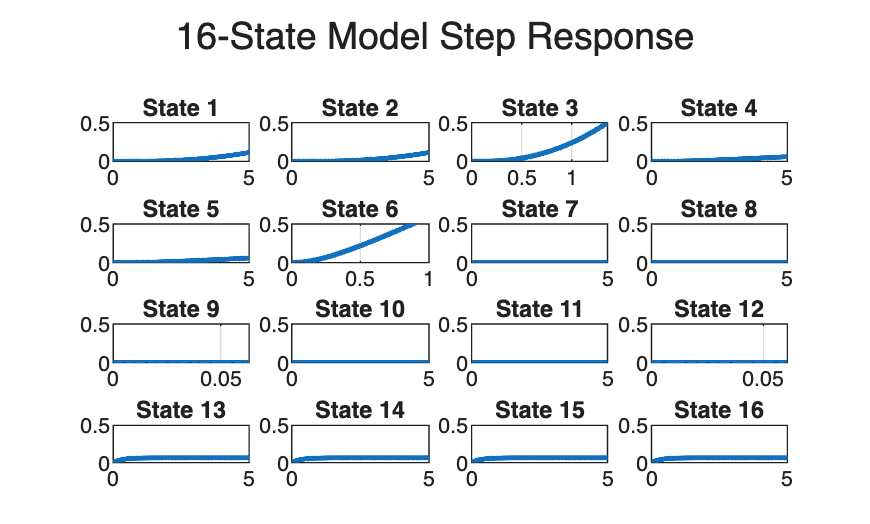

sys_sim = ss(A_2, B_2, C_2, D_2);

% 10% increase from hover
u_step = u0_2 *1.1; 

U_delta = (u_step - u0_2)'; 

t = 0:0.01:5;  % using the same sampling period .01s 
U = repmat(U_delta, length(t), 1); 

[y, tOut, x] = lsim(sys_sim, U, t);


for i = 1:16
    subplot(4, 4, i);
    plot(tOut, y(:,i), 'LineWidth', 2);
    ylim([0 0.5]);
    title(['State ' num2str(i)]);
    grid on;
end
sgtitle('16-State Model Step Response');

## Albert Visualization.

% 1. Extract Raw States (Inertial NED & Euler Angles in rads)
pn_sim = x(:, 1);
pe_sim = x(:, 2);
pd_sim = x(:, 3);
phi_sim   = x(:, 7);
theta_sim = x(:, 8);
psi_sim   = x(:, 9);

% 2. Define Drone Geometry for Plotting
arm_length = L; % 0.046m based on your params
d_geom = arm_length * (sqrt(2)/2);
% Define the 4 motor positions in the body frame (X-configuration)
motor_pos_body = [ d_geom, -d_geom, -d_geom,  d_geom;   % X coords
                   d_geom,  d_geom, -d_geom, -d_geom;   % Y coords
                   0,       0,       0,       0 ];      % Z coords

% 3. Set up the Figure
figure('Name', '3D Quadcopter Animation', 'Position', [100, 100, 800, 600]);
hold on; grid on; axis equal;
view([100, 45]); 

xlabel('East (m)');
ylabel('North (m)');
zlabel('Up (m)');
title('Quadcopter 3D Animation');

% Initialize graphics objects
drone_lines = plot3(0,0,0, '-k', 'LineWidth', 1);
motor_markers = plot3(0,0,0, 'ro', 'MarkerSize', 2, 'MarkerFaceColor', 'r');
path_trace = plot3(pe_sim(1), pn_sim(1), -pd_sim(1), 'b--', 'LineWidth', 1.5);

% Body Coordinate frame arrows (Red=X, Green=Y, Blue=Z)
scale_arrow = arm_length * 1.5;
q_x = quiver3(0,0,0, 1,0,0, scale_arrow, 'r', 'LineWidth', 1, 'MaxHeadSize', 0.5);
q_y = quiver3(0,0,0, 0,1,0, scale_arrow, 'g', 'LineWidth', 1, 'MaxHeadSize', 0.5);
q_z = quiver3(0,0,0, 0,0,1, scale_arrow, 'b', 'LineWidth', 1, 'MaxHeadSize', 0.5);

% 4. Animation Loop
disp('Starting 3D Animation...');

Starting 3D Animation...


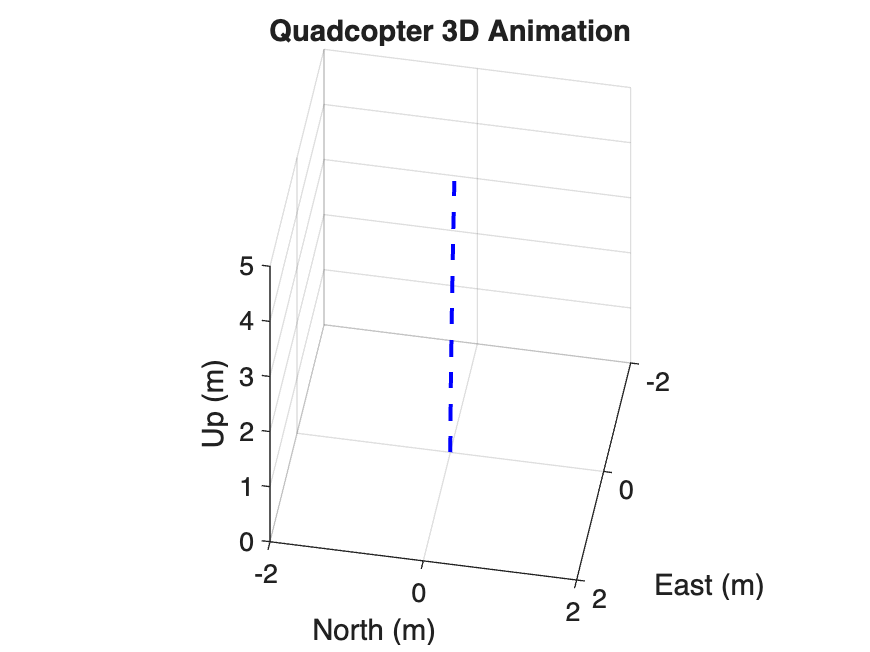

for k = 1:length(tOut)
    % Current position mapped to ENU (East, North, Up) for standard 3D viewing
    pos_enu = [pe_sim(k); pn_sim(k); -pd_sim(k)];
    
    % Current attitude 
    rll = phi_sim(k);
    ptc = theta_sim(k);
    yw  = psi_sim(k);
    
    % Rotation matrix: Body to Inertial (ZYX sequence matching your dynamics)
    Rx = [1 0 0; 0 cos(rll) -sin(rll); 0 sin(rll) cos(rll)];
    Ry = [cos(ptc) 0 sin(ptc); 0 1 0; -sin(ptc) 0 cos(ptc)];
    Rz = [cos(yw) -sin(yw) 0; sin(yw) cos(yw) 0; 0 0 1];
    R_b2i = Rz * Ry * Rx;
    
    % Transform matrix: NED to ENU for MATLAB plotting axes
    R_ned2enu = [0 1 0; 1 0 0; 0 0 -1];
    
    % Rotate geometry to Inertial (NED), convert to ENU, then translate
    motor_pos_ned = R_b2i * motor_pos_body;
    motor_pos_enu = R_ned2enu * motor_pos_ned + pos_enu;
    
    % Update drone cross-frame (motor 1 to 3, motor 2 to 4)
    X_arms = [motor_pos_enu(1,1), motor_pos_enu(1,3), NaN, motor_pos_enu(1,2), motor_pos_enu(1,4)];
    Y_arms = [motor_pos_enu(2,1), motor_pos_enu(2,3), NaN, motor_pos_enu(2,2), motor_pos_enu(2,4)];
    Z_arms = [motor_pos_enu(3,1), motor_pos_enu(3,3), NaN, motor_pos_enu(3,2), motor_pos_enu(3,4)];
    
    set(drone_lines, 'XData', X_arms, 'YData', Y_arms, 'ZData', Z_arms);
    set(motor_markers, 'XData', motor_pos_enu(1,:), 'YData', motor_pos_enu(2,:), 'ZData', motor_pos_enu(3,:));
    
    % Update body coordinate axes vectors
    axes_body = eye(3); 
    axes_ned = R_b2i * axes_body;
    axes_enu = R_ned2enu * axes_ned; 
    
    set(q_x, 'XData', pos_enu(1), 'YData', pos_enu(2), 'ZData', pos_enu(3), 'UData', axes_enu(1,1), 'VData', axes_enu(2,1), 'WData', axes_enu(3,1));
    set(q_y, 'XData', pos_enu(1), 'YData', pos_enu(2), 'ZData', pos_enu(3), 'UData', axes_enu(1,2), 'VData', axes_enu(2,2), 'WData', axes_enu(3,2));
    set(q_z, 'XData', pos_enu(1), 'YData', pos_enu(2), 'ZData', pos_enu(3), 'UData', axes_enu(1,3), 'VData', axes_enu(2,3), 'WData', axes_enu(3,3));
    
    % Update trajectory trace
    set(path_trace, 'XData', pe_sim(1:k), 'YData', pn_sim(1:k), 'ZData', -pd_sim(1:k));
    
    % Tracking Camera: Moves the view window to follow the drone 
    % (Because the drone is 4cm wide but might fly several meters up)
    xlim([-2, 2])
    ylim([-2, 2])
    zlim([0, 5])
    
    drawnow;
end

## Altitude Control

close all

% reduced - z, z_vel, and new z_error_int
A_z_aug = [0 1 0;
           0 0 0;
          -1 0 0]; % <-- should def become -1 (ENU)

B_z_aug = [0; 1/drone_mass_kg; 0];


Q_z = diag([10, 1, 100]); % penalizing state errors
R_z = 1; % penalizing control effort

K_z_fb = lqr(A_z_aug, B_z_aug, Q_z, R_z) % solve the risotto equation

K_z_fb =     5.7890    1.1756  -10.0000


Kp = K_z_fb(1); Ki = K_z_fb(2); Kd = K_z_fb(3);


A_closed_loop = A_z_aug - B_z_aug*K_z_fb

A_closed_loop =          0    1.0000         0
 -175.4237  -35.6247  303.0303
   -1.0000         0         0


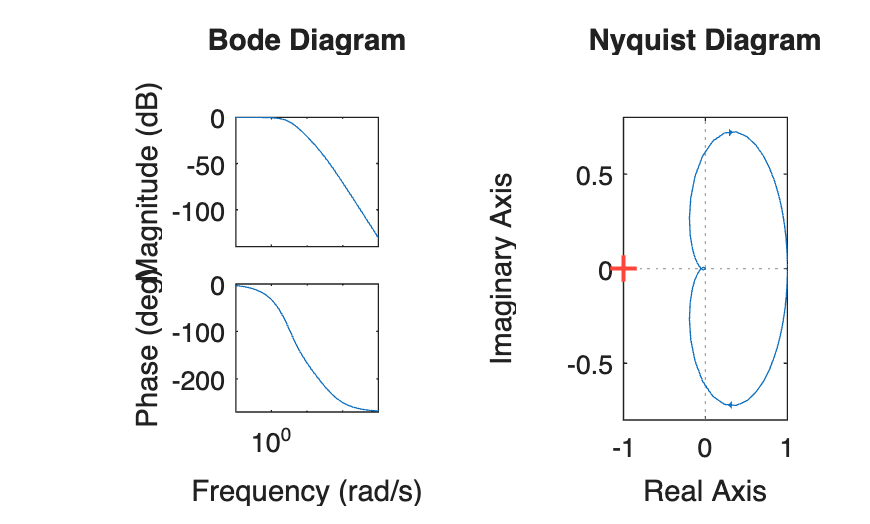




sys_cl = ss(A_closed_loop,[0;0;1],[1 0 0],0);

figure
subplot(1,2,1); bode(sys_cl)
subplot(1,2,2); nyquist(sys_cl);

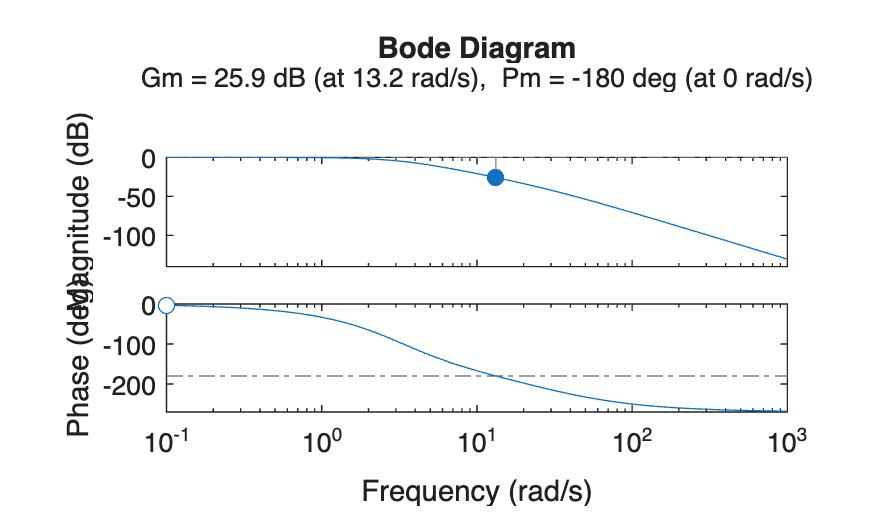


G = tf(sys_cl);
figure
margin(G)

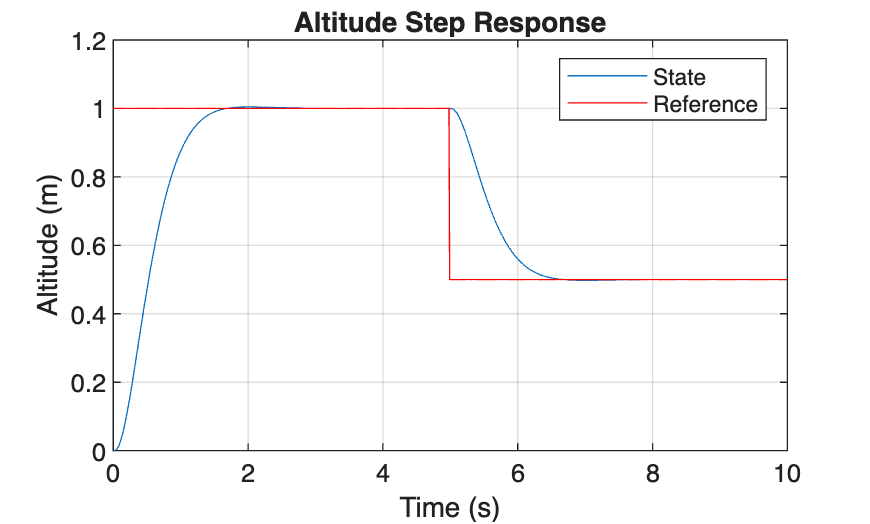


%---------------------------------
t = 0:0.01:10;

z_ref = ones(size(t)); z_ref(500:end) = 0.5;

%[y,t] = step(sys_cl,t);
[y, t, x] = lsim(sys_cl, z_ref, t);

figure
plot(t,y, 'DisplayName', 'State')
hold on
plot(t, z_ref, "r", 'DisplayName', 'Reference')
grid on
legend()
xlabel('Time (s)')
ylabel('Altitude (m)')
title('Altitude Step Response')

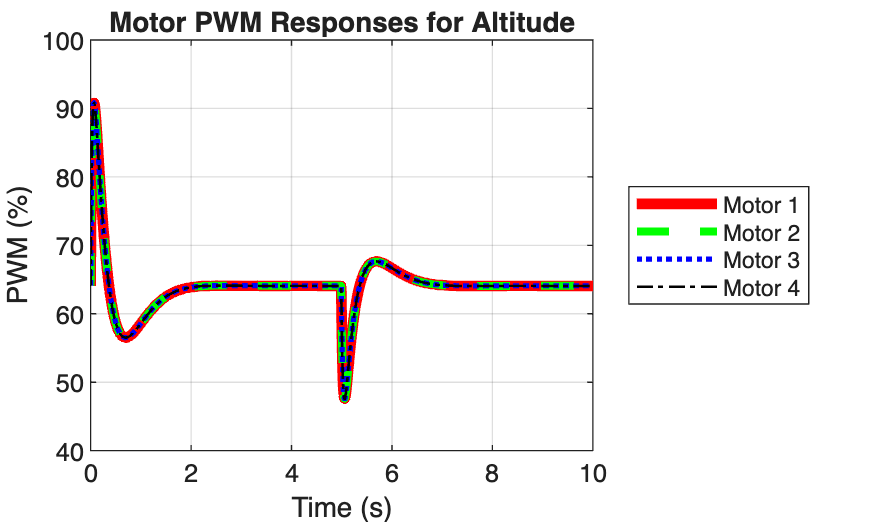




% Calculate the change in commanded force from the LQR controller
delta_F_cmd = (-K_z_fb * x')';

% Add the hover thrust (weight of the drone) back in
F_hover = drone_mass_kg * 9.81;
F_total_cmd = F_hover + delta_F_cmd;

% Run the total force through mixer for every time step
pwm_hist = zeros(length(t), 4);
for i = 1:length(t)
    % Mix total thrust with 0 roll, 0 pitch, and 0 yaw moments
    [pwm_pct, ~] = quad_mixer(F_total_cmd(i), 0, 0, 0, A_thrust, B_thrust, d, C_tau, F_min, F_max);
    pwm_hist(i, :) = pwm_pct';
end

% Plot the PWM responses (using different line styles so they don't hide each other)
figure
plot(t, pwm_hist(:,1), 'r-',  'LineWidth', 4, 'DisplayName', 'Motor 1'); hold on;
plot(t, pwm_hist(:,2), 'g--', 'LineWidth', 3, 'DisplayName', 'Motor 2');
plot(t, pwm_hist(:,3), 'b:',  'LineWidth', 2, 'DisplayName', 'Motor 3');
plot(t, pwm_hist(:,4), 'k-.', 'LineWidth', 1, 'DisplayName', 'Motor 4');

title('Motor PWM Responses for Altitude');
xlabel('Time (s)'); ylabel('PWM (%)');
legend('Location', 'EastOutside'); grid on;

## Forward Position Control

close all

A_pn = [0 1 0 0;
        0 0 -9.81 0;
        0 0 0 1;
        0 0 0 0];
B_pn = [0; 0; 0; 1/J(2,2)];




% state p, u, theta, q
A_pn_aug = [0 1 0 0 0;
            0 0 -9.81 0 0;
            0 0 0 1 0;
            0 0 0 0 0;
            1 0 0 0 0]; % might need to change this row

B_pn_aug = [0; 0; 0; 1/J(2,2); 0];

Q_pn = diag([10, 10, 100, 10, 100]); % penalizing state errors
R_pn = 1e9; % penalizing control effort

K_pn = lqr(A_pn_aug, B_pn_aug, Q_pn, R_pn) % solve alfredo equation

K_pn =    -0.0006   -0.0006    0.0031    0.0010   -0.0003


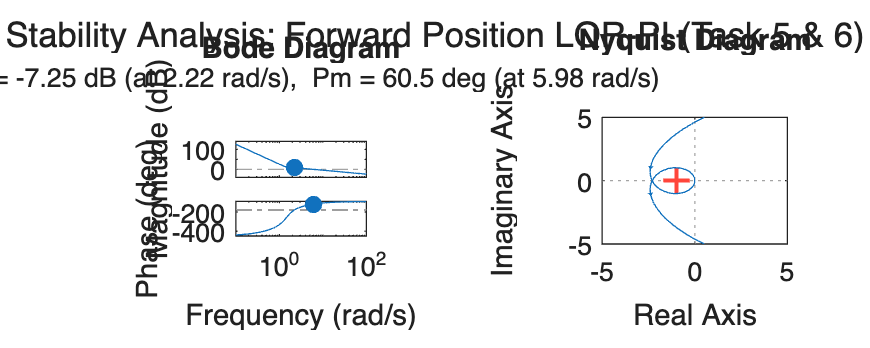



%Stability Analysis -------------------------------------------------
% 5 & 6. Open-Loop Transfer Function and Margins
% Break the loop at the plant input. 
% P(s) = C_long * (sI - A_long)^-1 * B_long
% C(s) = K(1:4) * (sI - A_long + B_long*K(1:4))^-1 * B_long + K(5)/s  (Simplified approach below uses ss arrays)
sys_P = ss(A_pn, B_pn, eye(4), zeros(4,1));
L_ol_long = ss(A_pn_aug, B_pn_aug, K_pn, 0);

figure('Name', 'Forward Position Stability', 'Position', [150, 100, 1000, 400]);
subplot(1,2,1); margin(L_ol_long);
subplot(1,2,2); nyquist(L_ol_long);
xlim([-5, 5])
ylim([-5, 5])
sgtitle('Stability Analysis: Forward Position LQR-PI (Task 5 & 6)');


[Gm_long, Pm_long, ~, ~] = margin(L_ol_long);
fprintf('Gain Margin: %.2f dB, Phase Margin: %.2f deg\n', 20*log10(Gm_long), Pm_long);

Gain Margin: -7.25 dB, Phase Margin: 60.45 deg


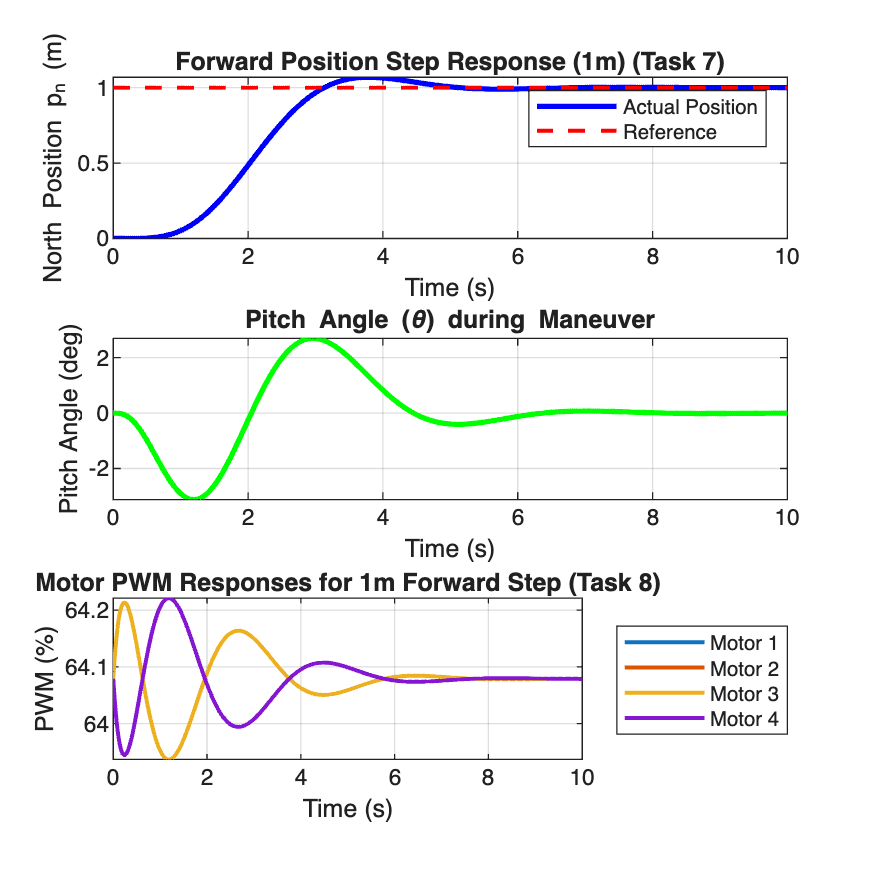


%Closed-Loop Simulation -------------------------------------------

B_ref_pn = [0; 0; 0; 0; -1]; % -1 for integral state
sys_cl_long = ss(A_pn_aug - B_pn_aug*K_pn, B_ref_pn, eye(5), zeros(5,1)); % (A - BK)

t_sim = 0:0.01:10; % Slightly longer simulation to show settling
pn_ref_step = ones(size(t_sim)); % 1 meter step command
[y_cl_long, t_cl, x_cl_long] = lsim(sys_cl_long, pn_ref_step, t_sim);

figure('Name', 'Forward Position Step Response & PWM', 'Position', [200, 150, 800, 800]);
subplot(3,1,1);
plot(t_cl, x_cl_long(:,1), 'b', 'LineWidth', 2); hold on;
plot(t_cl, pn_ref_step, 'r--', 'LineWidth', 1.5);
title('Forward Position Step Response (1m) (Task 7)');
xlabel('Time (s)'); ylabel('North Position p_n (m)');
legend('Actual Position', 'Reference'); grid on;

subplot(3,1,2);
plot(t_cl, x_cl_long(:,3)*(180/pi), 'g', 'LineWidth', 2);
title('Pitch Angle (\theta) during Maneuver');
xlabel('Time (s)'); ylabel('Pitch Angle (deg)'); grid on;


% PWM behavior with Mixer ------------------------------------------------
M_cmd = -x_cl_long * K_pn';
F_hover = drone_mass_kg * 9.81; % We must maintain altitude!

pwm_hist_long = zeros(length(t_cl), 4);
for i = 1:length(t_cl)
    % Mix hover thrust with commanded pitching moment. Roll and Yaw are 0.
    [pwm_pct, ~] = quad_mixer(F_hover, 0, M_cmd(i), 0, A_thrust, B_thrust, d, C_tau, F_min, F_max);
    pwm_hist_long(i, :) = pwm_pct';
end

subplot(3,1,3);
plot(t_cl, pwm_hist_long, 'LineWidth', 1.5);
title('Motor PWM Responses for 1m Forward Step (Task 8)');
xlabel('Time (s)'); ylabel('PWM (%)');
legend('Motor 1', 'Motor 2', 'Motor 3', 'Motor 4', 'Location', 'EastOutside'); grid on;

## Lateral Position Control

close all

% reduced state can be pe, v, phi, p
A_pe = [0 1 0 0;
        0 0 9.81 0;
        0 0 0 1;
        0 0 0 0];

B_pe = [0; 0; 0; 1/J(1,1)];

A_pe_aug = [0 1 0 0 0;
            0 0 -9.81 0 0;
            0 0 0 1 0;
            0 0 0 0 0;
            1 0 0 0 0];

B_pe_aug = [B_pe; 0];

Q_pe = diag([10, 10, 100, 10, 100]); % penalizing state errors
R_pe = 1e9; % penalizing control effort

K_pe = lqr(A_pe_aug, B_pe_aug, Q_pe, R_pe)

K_pe =    -0.0006   -0.0006    0.0031    0.0010   -0.0003


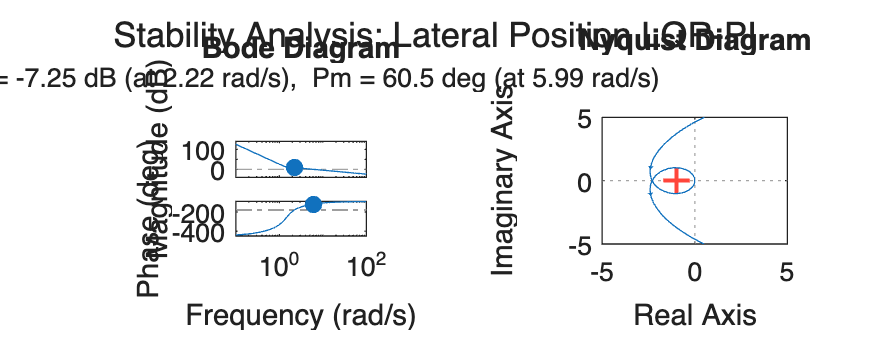




%Transfer Functions and Stability ------------------------------------

%open loop TF
sys_L_ol = ss(A_pe_aug, B_pe_aug, K_pe, 0);

figure('Name', 'Lateral Position Stability', 'Position', [150, 100, 1000, 400]);
subplot(1,2,1); margin(sys_L_ol);
subplot(1,2,2); nyquist(sys_L_ol);
xlim([-5, 5])
ylim([-5, 5])
sgtitle('Stability Analysis: Lateral Position LQR-PI');


[Gm_lat, Pm_lat, ~, ~] = margin(sys_L_ol);
fprintf('Gain Margin: %.2f dB, Phase Margin: %.2f deg\n', 20*log10(Gm_lat), Pm_lat);

Gain Margin: -7.25 dB, Phase Margin: 60.45 deg


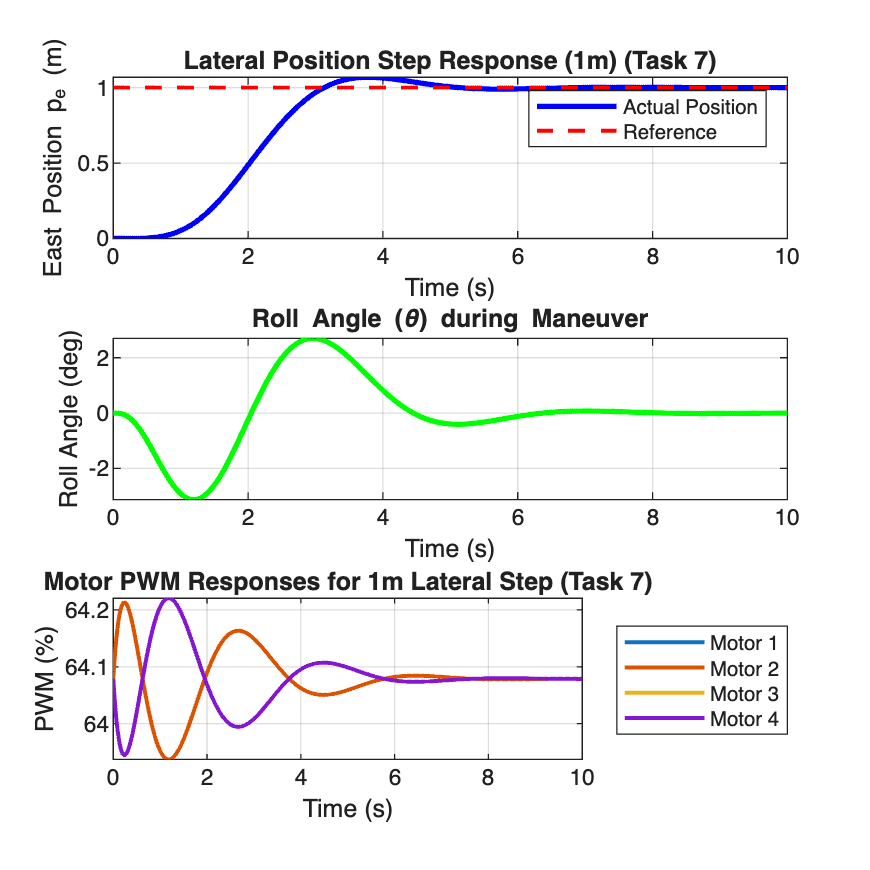



%Closed-Loop Simulation -------------------------------------------

B_ref_pe = [0; 0; 0; 0; -1]; % -1 for integral state
sys_cl_lat = ss(A_pe_aug - B_pe_aug*K_pe, B_ref_pe, eye(5), zeros(5,1)); % (A - BK) + B

t_sim = 0:0.01:10; % Slightly longer simulation to show settling
pe_ref_step = ones(size(t_sim)); % 1 meter step command
[y_cl_lat, t_cl, x_cl_lat] = lsim(sys_cl_lat, pe_ref_step, t_sim);

figure('Name', 'Lateral Position Step Response & PWM', 'Position', [200, 150, 800, 800]);
subplot(3,1,1);
plot(t_cl, x_cl_lat(:,1), 'b', 'LineWidth', 2); hold on;
plot(t_cl, pe_ref_step, 'r--', 'LineWidth', 1.5);
title('Lateral Position Step Response (1m) (Task 7)');
xlabel('Time (s)'); ylabel('East Position p_e (m)');
legend('Actual Position', 'Reference'); grid on;

subplot(3,1,2);
plot(t_cl, x_cl_lat(:,3)*(180/pi), 'g', 'LineWidth', 2);
title('Roll Angle (\theta) during Maneuver');
xlabel('Time (s)'); ylabel('Roll Angle (deg)'); grid on;


% PWM behavior with Mixer ------------------------------------------------
L_cmd = -x_cl_lat * K_pe';
F_hover = drone_mass_kg * 9.81; % We must maintain altitude!

pwm_hist_lat = zeros(length(t_cl), 4);
for i = 1:length(t_cl)
    % Mix hover thrust with commanded pitching moment. Roll and Yaw are 0.
    [pwm_pct, ~] = quad_mixer(F_hover, L_cmd(i), 0, 0, A_thrust, B_thrust, d, C_tau, F_min, F_max);
    pwm_hist_lat(i, :) = pwm_pct';
end

subplot(3,1,3);
plot(t_cl, pwm_hist_lat, 'LineWidth', 1.5);
title('Motor PWM Responses for 1m Lateral Step (Task 7)');
xlabel('Time (s)'); ylabel('PWM (%)');
legend('Motor 1', 'Motor 2', 'Motor 3', 'Motor 4', 'Location', 'EastOutside'); grid on;

## Yaw Rate Control


close all

% reduced state: x = [r] (yaw rate in rad/s)
A_yaw = 0; 
B_yaw = 1/J(3,3); 

Q_yaw = 10; % Penalize yaw rate error
R_yaw = 1;  % Penalize control effort

K_yaw = lqr(A_yaw, B_yaw, Q_yaw, R_yaw)

K_yaw = 3.1623

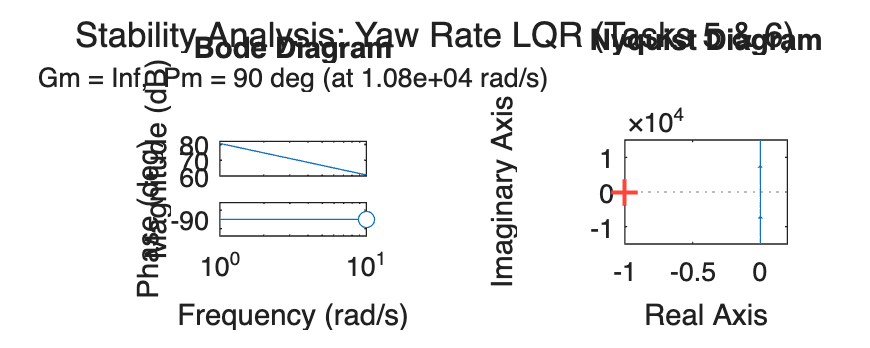


% open loop system
sys_L_ol_yaw = ss(A_yaw, B_yaw, K_yaw, 0);

figure('Name', 'Yaw Rate Stability', 'Position', [150, 100, 1000, 400]);
subplot(1,2,1); margin(sys_L_ol_yaw);
subplot(1,2,2); nyquist(sys_L_ol_yaw);
sgtitle('Stability Analysis: Yaw Rate LQR (Tasks 5 & 6)');


[Gm_yaw, Pm_yaw, ~, ~] = margin(sys_L_ol_yaw);
fprintf('Yaw Gain Margin: %.2f dB, Phase Margin: %.2f deg\n', 20*log10(Gm_yaw), Pm_yaw);

Yaw Gain Margin: Inf dB, Phase Margin: 90.00 deg


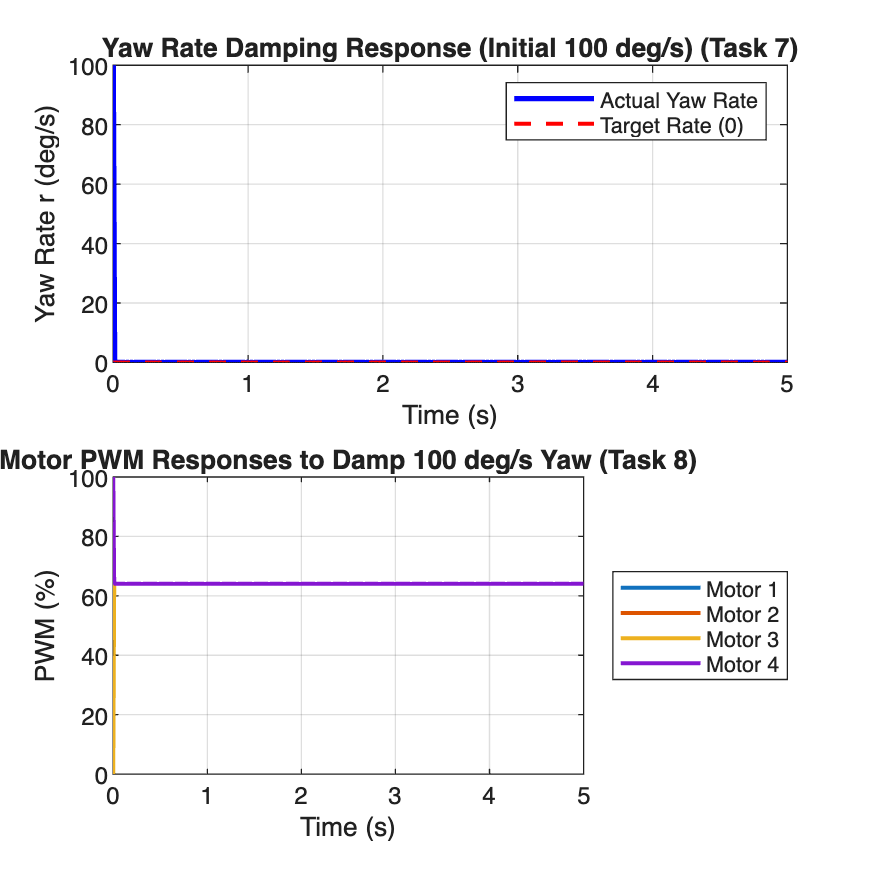


% closed loop 
sys_cl_yaw = ss(A_yaw - B_yaw*K_yaw, B_yaw, 1, 0); 

t_sim = 0:0.01:5; 
r_ref = zeros(size(t_sim)); % yaw rate to go to zero

% Damp a 100 deg/s initial yaw rate
r0_rad = 100 * (pi/180); 
x0_yaw = r0_rad;

[y_cl_yaw, t_cl, x_cl_yaw] = lsim(sys_cl_yaw, r_ref, t_sim, x0_yaw);

figure('Name', 'Yaw Rate Damping & PWM', 'Position', [200, 150, 800, 800]);

% Plot the yaw rate
subplot(2,1,1);
plot(t_cl, x_cl_yaw(:,1) * (180/pi), 'b', 'LineWidth', 2); hold on;
plot(t_cl, r_ref, 'r--', 'LineWidth', 1.5);
title('Yaw Rate Damping Response (Initial 100 deg/s) (Task 7)');
xlabel('Time (s)'); ylabel('Yaw Rate r (deg/s)');
legend('Actual Yaw Rate', 'Target Rate (0)'); grid on;

% PWM behavior with Mixer ------------------------------------------------
N_cmd = -x_cl_yaw * K_yaw;
F_hover = drone_mass_kg * 9.81; % Maintain altitude!

pwm_hist_yaw = zeros(length(t_cl), 4);
for i = 1:length(t_cl)
    % Mix hover thrust with commanded yawing moment. Roll and Pitch are 0.
    [pwm_pct, ~] = quad_mixer(F_hover, 0, 0, N_cmd(i), A_thrust, B_thrust, d, C_tau, F_min, F_max);
    pwm_hist_yaw(i, :) = pwm_pct';
end

subplot(2,1,2);
plot(t_cl, pwm_hist_yaw, 'LineWidth', 1.5);
title('Motor PWM Responses to Damp 100 deg/s Yaw (Task 8)');
xlabel('Time (s)'); ylabel('PWM (%)');
legend('Motor 1', 'Motor 2', 'Motor 3', 'Motor 4', 'Location', 'EastOutside'); grid on;